# AtmoData Processing

Brendan Apple

Creates the most relevant graphs from data collected by the Atmospheric Data Sensor on Cardinal, which was created by NCSSM's High Powered Rocketry Team.

warning off
clear,clc,close

#### Loads in All the Data

Raw = readlines("DATALOG_ADJ.TXT")

Raw = 5741×1 string array
    "1671 - 0m :1s : 671ms :     tm 20.90, hd 33.07, he 0, iaq , tvoc 0, eco2 400, iaqr , h2 14862, eth 18745, ori 0.00 0.00 0.00, gyr 0.00 0.00 0.00, lin 0.00 0.00 0.00, mag 0.00 0.00 0.00, accl 0.00 0.00 0.00, grav 0.00 0.00 0.00, xpos 0.00, ypos 0.00, head 0.00"
    "1850 - 0m :1s : 850ms :     tm 20.91, hd 33.04, he 0, iaq , tvoc 0, eco2 400, iaqr , h2 14864, eth 18747, ori 0.00 0.00 0.00, gyr 0.00 0.00 0.00, lin 0.00 0.00 0.00, mag 0.00 0.00 0.00, accl 0.00 0.00 0.00, grav 0.00 0.00 0.00, xpos 0.00, ypos 0.00, head 0.00"
    "2026 - 0m :2s : 26ms :     tm 20.93, hd 33.11, he 0, iaq , tvoc 0, eco2 400, iaqr , h2 14874, eth 18764, ori 0.00 0.00 0.00, gyr 0.00 0.00 0.00, lin 0.00 0.00 0.00, mag 0.00 0.00 0.00, accl 0.00 0.00 0.00, grav 0.00 0.00 0.00, xpos 0.00, ypos 0.00, head 0.00"
    "2207 - 0m :2s : 207ms :     tm 20.93, hd 33.10, he 0, iaq , tvoc 0, eco2 400, iaqr , h2 14874, eth 18760, ori 0.00 0.31 38.25, gyr -0.00 -0.00 0.00, lin 0.00 0.63 -0.92, ma

DataLength = length(Raw)

DataLength = 5741

Time = zeros(1,DataLength);
Min = zeros(1,DataLength);
Sec = zeros(1,DataLength);
MS = zeros(1,DataLength);
Temperature = zeros(1,DataLength);
Humidity = zeros(1,DataLength);
Heater = zeros(1,DataLength);
TVOC = zeros(1,DataLength);
CO2 = zeros(1,DataLength);
H2 = zeros(1,DataLength);
Ethanol = zeros(1,DataLength);
Orientation_X = zeros(1,DataLength);
Orientation_Y = zeros(1,DataLength);
Orientation_Z = zeros(1,DataLength);
Gyrometer_X = zeros(1,DataLength);
Gyrometer_Y = zeros(1,DataLength);
Gyrometer_Z = zeros(1,DataLength);
Gyrometer_Total = zeros(1,DataLength);
Linear_X = zeros(1,DataLength);
Linear_Y = zeros(1,DataLength);
Linear_Z = zeros(1,DataLength);
Linear_Total = zeros(1,DataLength);
Magnetic_X = zeros(1,DataLength);
Magnetic_Y = zeros(1,DataLength);
Magnetic_Z = zeros(1,DataLength);
Magnetic_Total = zeros(1,DataLength);
Acceleration_X = zeros(1,DataLength);
Acceleration_Y = zeros(1,DataLength);
Acceleration_Z = zeros(1,DataLength);
Acceleration_Total = zeros(1,DataLength);
Gravity_X = zeros(1,DataLength);
Gravity_Y = zeros(1,DataLength);
Gravity_Z = zeros(1,DataLength);
Gravity_Total = zeros(1,DataLength);
Position_X = zeros(1,DataLength);
Position_Y = zeros(1,DataLength);
Position_Head = zeros(1,DataLength);

for i = 1:length(Raw)
    TempArr = split(Raw(i), " ");
    
    Time(i) = str2double(TempArr(1,1));
    Min(i) = str2double(extractBefore(TempArr(3,1), "m"));
    Sec(i) = str2double(extractBetween(TempArr(4,1), ":", "s"));
    MS(i) = str2double(extractBefore(TempArr(6,1), "ms"));
    Temperature(i) = str2double(extractBefore(TempArr(13,1), ","));
    Humidity(i) = str2double(extractBefore(TempArr(15,1), ","));
    Heater(i) = str2double(extractBefore(TempArr(17,1), ","));
    TVOC(i) = str2double(extractBefore(TempArr(21,1), ","));
    CO2(i) = str2double(extractBefore(TempArr(23,1), ","));
    H2(i) = str2double(extractBefore(TempArr(27,1), ","));
    Ethanol(i) = str2double(extractBefore(TempArr(29,1), ","));
    Orientation_X(i) = str2double(TempArr(31,1));
    Orientation_Y(i) = str2double(TempArr(32,1));
    Orientation_Z(i) = str2double(extractBefore(TempArr(33,1), ","));
    Gyrometer_X(i) = str2double(TempArr(35,1));
    Gyrometer_Y(i) = str2double(TempArr(36,1));
    Gyrometer_Z(i) = str2double(extractBefore(TempArr(37,1), ","));
    Gyrometer_Total(i) = Gyrometer_X(i) + Gyrometer_Y(i) + Gyrometer_Z(i);
    Linear_X(i) = str2double(TempArr(39,1));
    Linear_Y(i) = str2double(TempArr(40,1));
    Linear_Z(i) = str2double(extractBefore(TempArr(41,1), ","));
    Linear_Total(i) = Linear_X(i) + Linear_Y(i) + Linear_Z(i);
    Magnetic_X(i) = str2double(TempArr(43,1));
    Magnetic_Y(i) = str2double(TempArr(44,1));
    Magnetic_Z(i) = str2double(extractBefore(TempArr(45,1), ","));
    Magnetic_Total(i) = Magnetic_X(i) + Magnetic_Y(i) + Magnetic_Z(i);
    Acceleration_X(i) = str2double(TempArr(47,1));
    Acceleration_Y(i) = str2double(TempArr(48,1));
    Acceleration_Z(i) = str2double(extractBefore(TempArr(49,1), ","));
    Acceleration_Total(i) = Acceleration_X(i) + Acceleration_Y(i) + Acceleration_Z(i);
    Gravity_X(i) = str2double(TempArr(51,1));
    Gravity_Y(i) = str2double(TempArr(52,1));
    Gravity_Z(i) = str2double(extractBefore(TempArr(53,1), ","));
    Gravity_Total(i) = Gravity_X(i) + Gravity_Y(i) + Gravity_Z(i);
    Position_X(i) = str2double(extractBefore(TempArr(55,1), ","));
    Position_Y(i) = str2double(extractBefore(TempArr(57,1), ","));
    Position_Head(i) = str2double(TempArr(59,1));

end

Time = Time';
Min = Min';
Sec = Sec';
MS = MS';
Temperature = Temperature';
Humidity = Humidity';
Heater = Heater';
TVOC = TVOC';
CO2 = CO2';
H2 = H2';
Ethanol = Ethanol';
Orientation_X = Orientation_X';
Orientation_Y = Orientation_Y';
Orientation_Z = Orientation_Z';
Gyrometer_X = Gyrometer_X';
Gyrometer_Y = Gyrometer_Y';
Gyrometer_Z = Gyrometer_Z';
Gyrometer_Total = Gyrometer_Total';
Linear_X = Linear_X';
Linear_Y = Linear_Y';
Linear_Z = Linear_Z';
Linear_Total = Linear_Total';
Magnetic_X = Magnetic_X';
Magnetic_Y = Magnetic_Y';
Magnetic_Z = Magnetic_Z';
Magnetic_Total = Magnetic_Total';
Acceleration_X = Acceleration_X';
Acceleration_Y = Acceleration_Y';
Acceleration_Z = Acceleration_Z';
Acceleration_Total = Acceleration_Total';
Gravity_X = Gravity_X';
Gravity_Y = Gravity_Y';
Gravity_Z = Gravity_Z';
Gravity_Total = Gravity_Total';
Position_X = Position_X';
Position_Y = Position_Y';
Position_Head = Position_Head';

AtmoTable = table(Time, Min, Sec, MS, Temperature, Humidity, Heater, TVOC, CO2, H2, Ethanol, ...
    Orientation_X, Orientation_Y, Orientation_Z, Gyrometer_X, Gyrometer_Y, Gyrometer_Z, Gyrometer_Total, Linear_X, Linear_Y, Linear_Z, Linear_Total, ...
    Magnetic_X, Magnetic_Y, Magnetic_Z, Magnetic_Total, Acceleration_X, Acceleration_Y, Acceleration_Z, Acceleration_Total, Gravity_X, Gravity_Y, Gravity_Z, Gravity_Total, ...
    Position_X, Position_Y, Position_Head)

AtmoTable = 5741×37 table
    Time    Min    Sec    MS     Temperature    Humidity    Heater    TVOC    CO2     H2      Ethanol    Orientation_X    Orientation_Y    Orientation_Z    Gyrometer_X    Gyrometer_Y    Gyrometer_Z    Gyrometer_Total    Linear_X    Linear_Y    Linear_Z    Linear_Total    Magnetic_X    Magnetic_Y    Magnetic_Z    Magnetic_Total    Acceleration_X    Acceleration_Y    Acceleration_Z    Acceleration_Total    Gravity_X    Gravity_Y

writetable(AtmoTable, "Datalog.csv")

## Analysis

`/* Board layout:`

`            +----------+`

`            |         *| RST   PITCH  ROLL  HEADING`

`        ADR |*        *| SCL`

`        INT |*        *| SDA     ^            /->`

`        PS1 |*        *| GND     |            |`

`        PS0 |*        *| 3VO     Y    Z-->    \-X`

`            |         *| VIN`

`            +----------+`

`      */`

#### Temperature (C) and Humidity (Relative %) vs Time

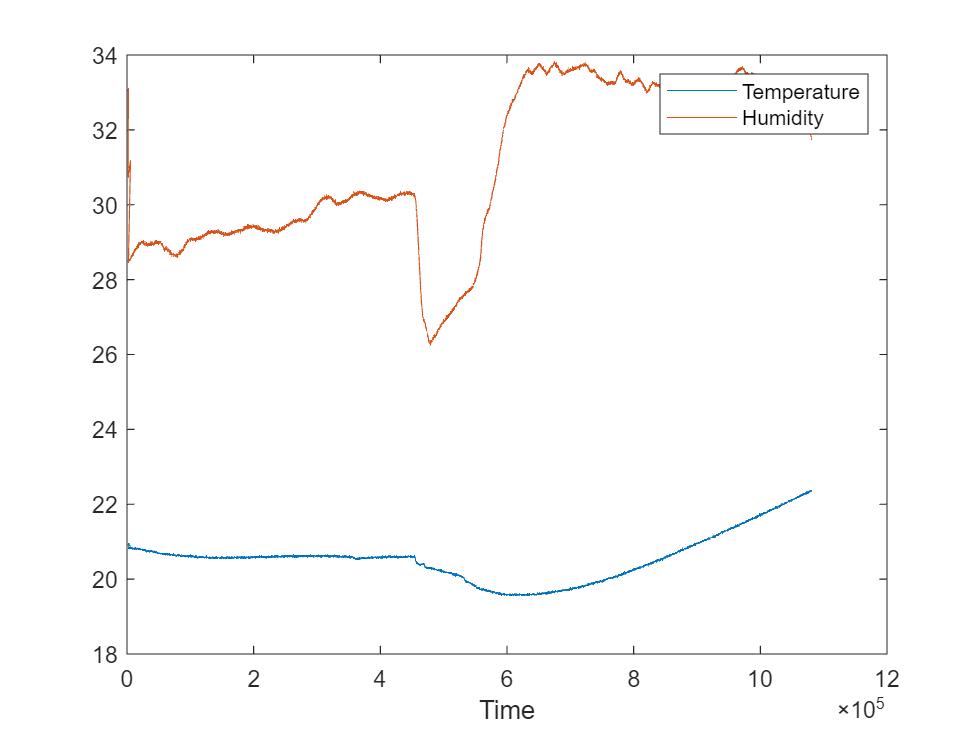

TemperaturePlot = plot(AtmoTable, "Time", ["Temperature", "Humidity"]);
legend

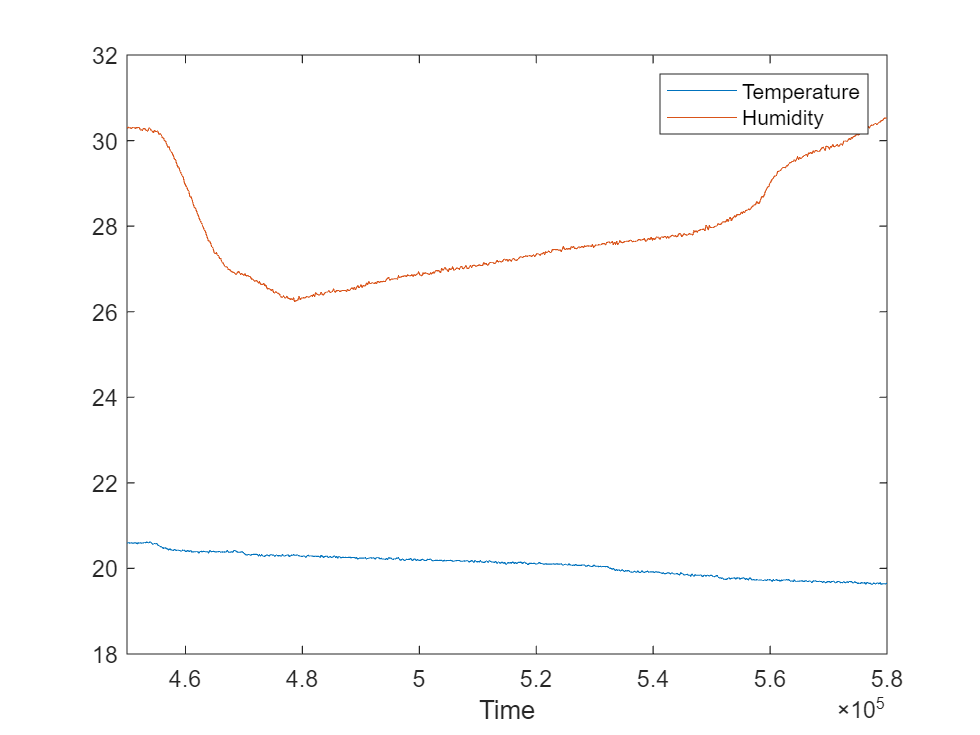

TemperaturePlot = plot(AtmoTable, "Time", ["Temperature", "Humidity"]);
xlim([450000,580000]);
legend

#### TVOC (ppb) and CO2 (ppm) vs Time

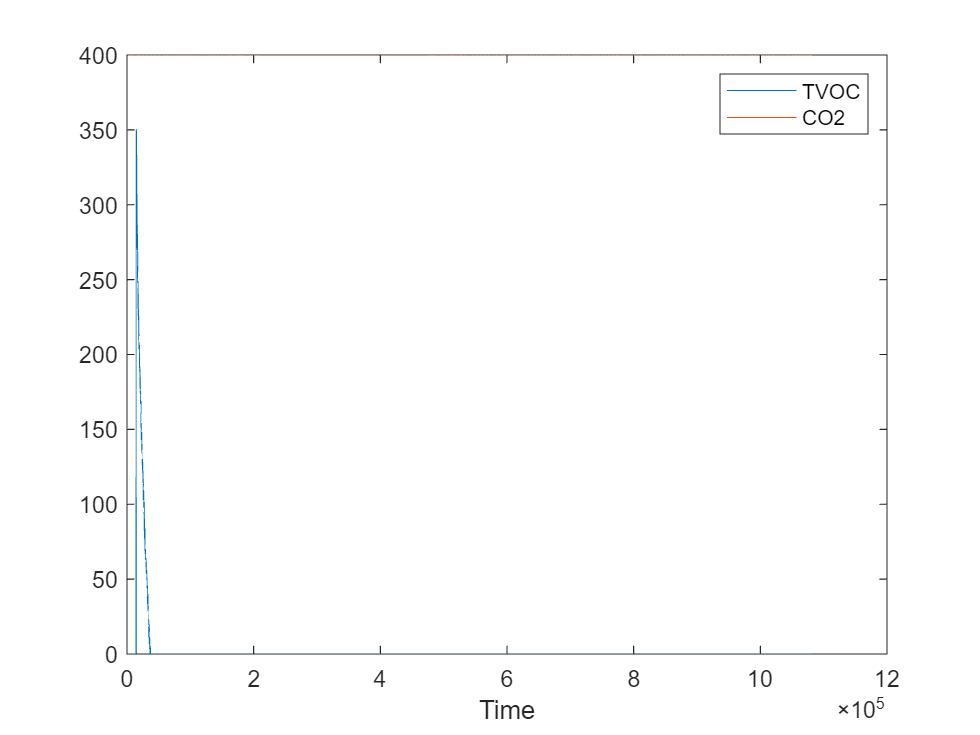

TemperaturePlot = plot(AtmoTable, "Time", ["TVOC", "CO2"]);
legend

#### H2 and Ethanol vs Time

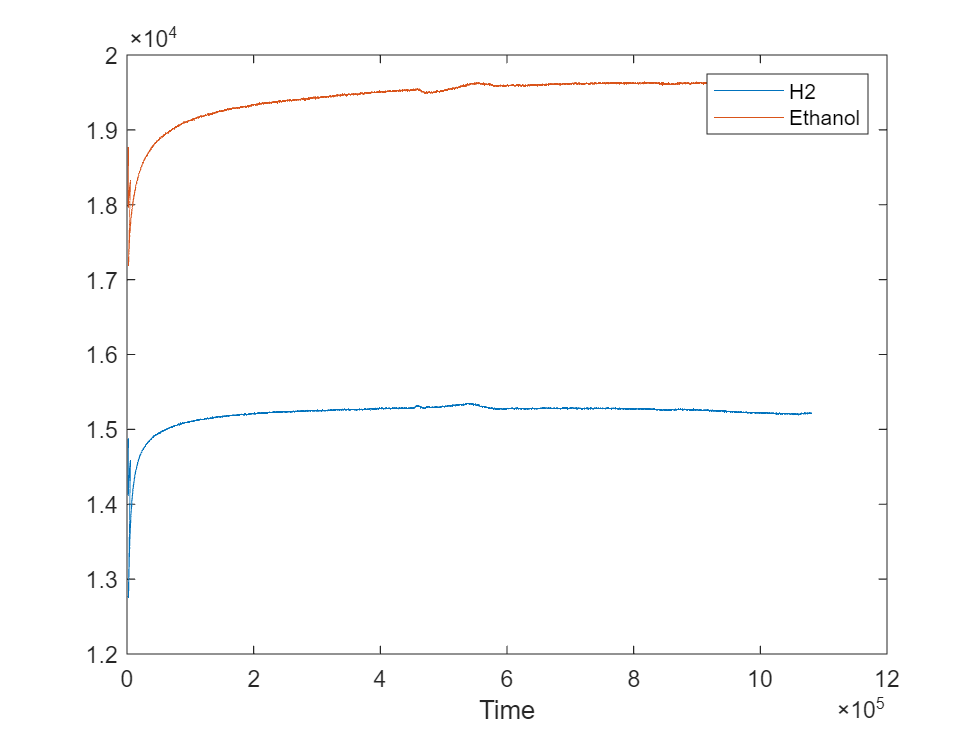

TemperaturePlot = plot(AtmoTable, "Time", ["H2", "Ethanol"]);
legend

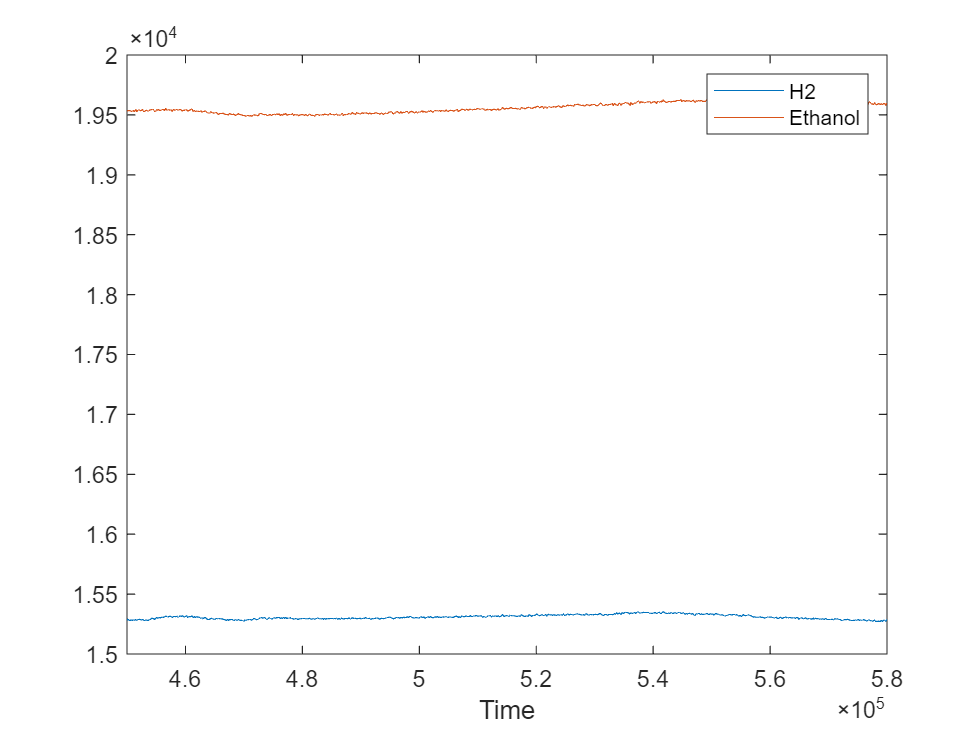

TemperaturePlot = plot(AtmoTable, "Time", ["H2", "Ethanol"]);
xlim([450000,580000]);
legend

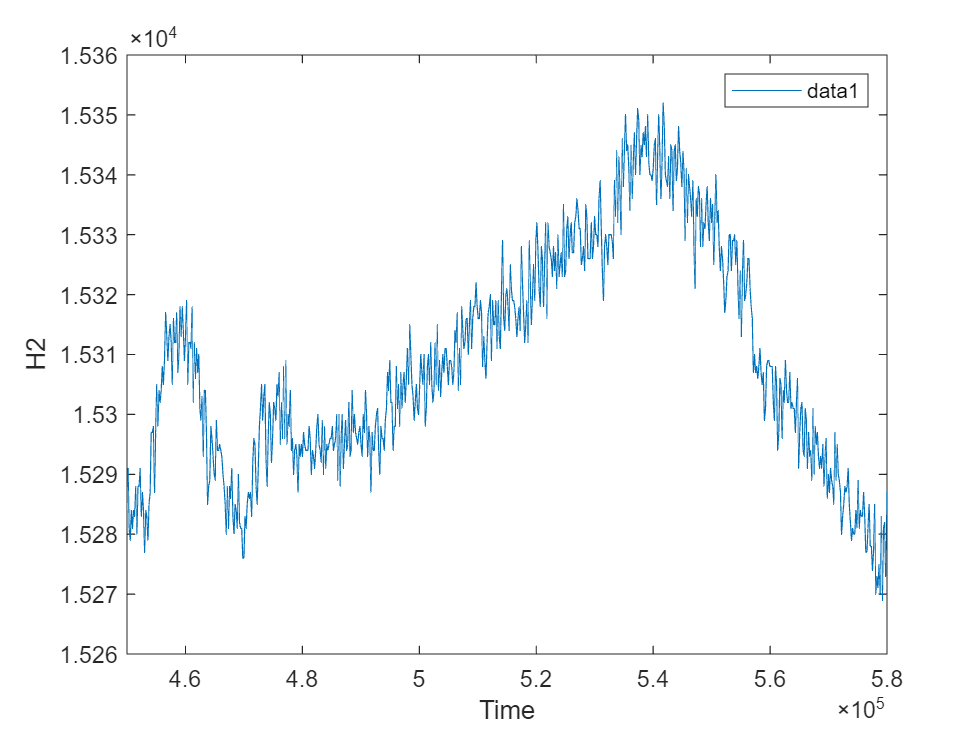

TemperaturePlot = plot(AtmoTable, "Time", "H2");
xlim([450000,580000]);
legend

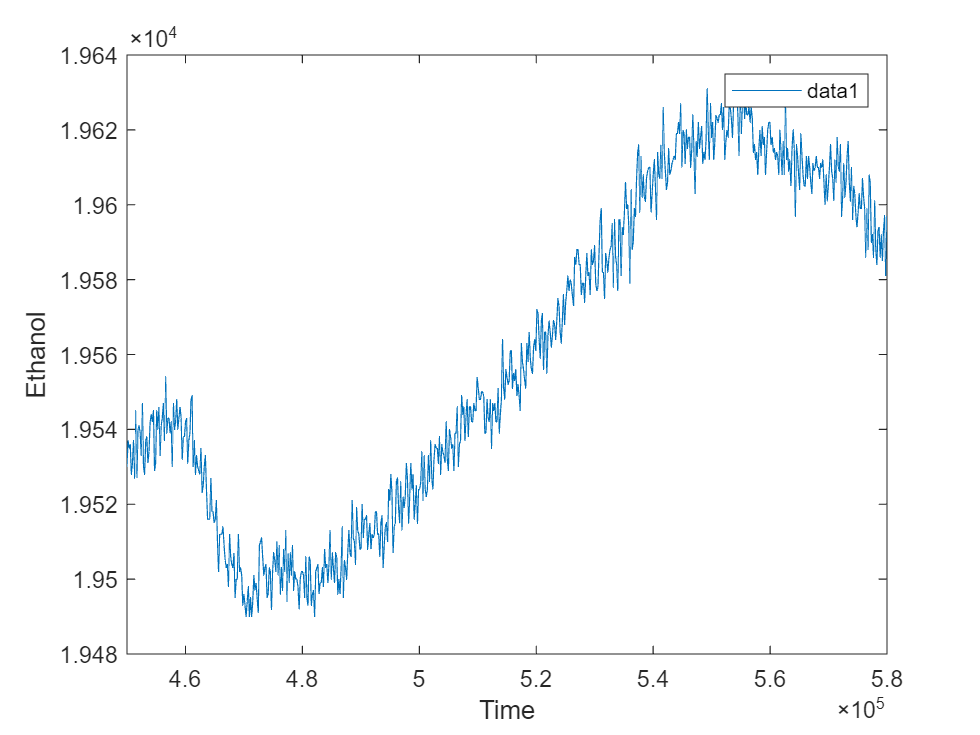

TemperaturePlot = plot(AtmoTable, "Time", "Ethanol");
xlim([450000,580000]);
legend

#### Orientation (degrees) vs Time

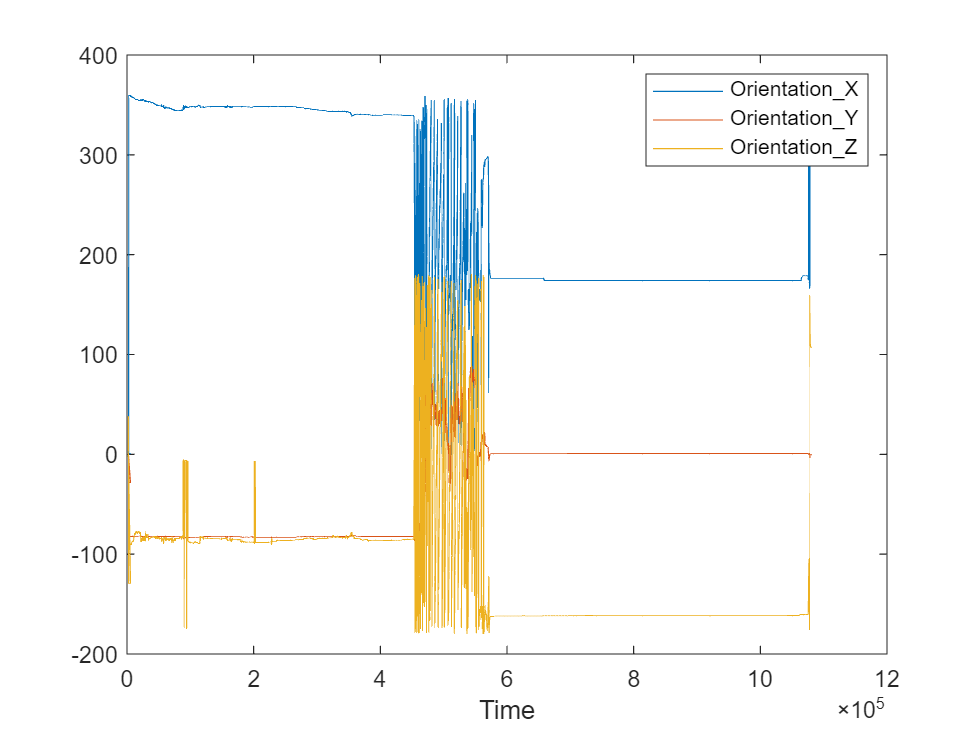

TemperaturePlot = plot(AtmoTable, "Time", ["Orientation_X", "Orientation_Y", "Orientation_Z"]);
legend

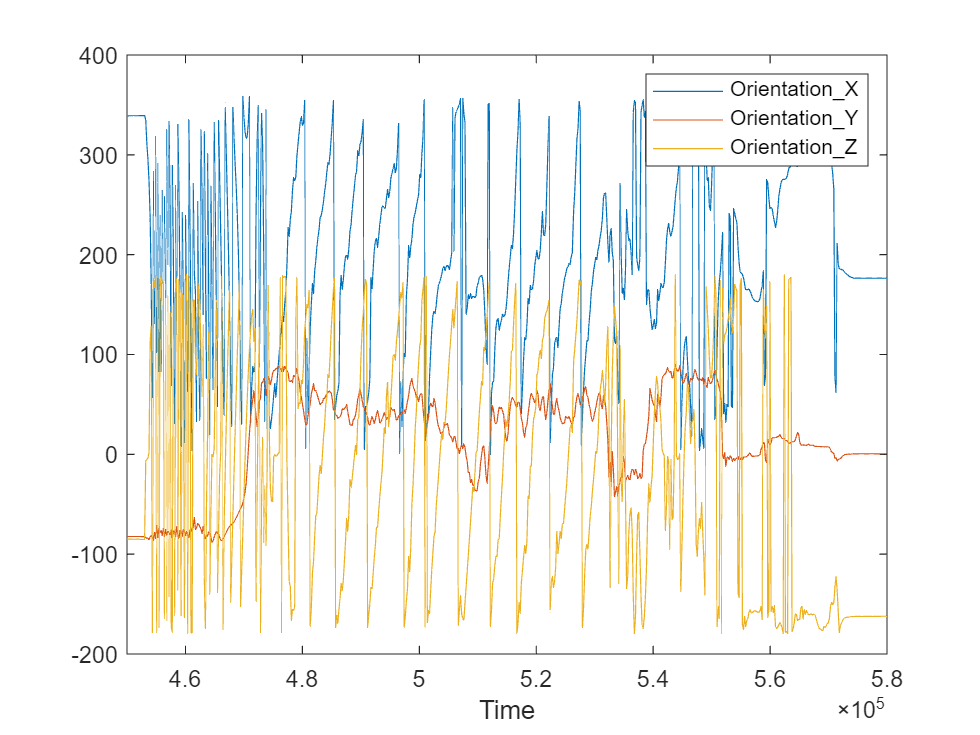

TemperaturePlot = plot(AtmoTable, "Time", ["Orientation_X", "Orientation_Y", "Orientation_Z"]);
xlim([450000,580000]);
legend

#### Gyroscope (rad/s) vs Time

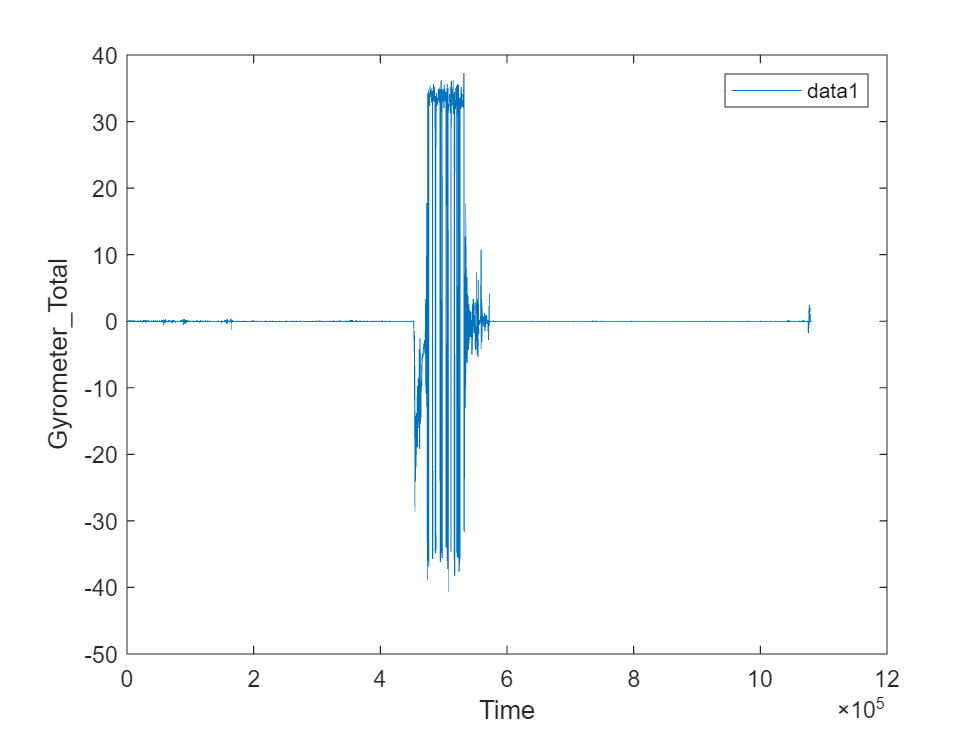

TemperaturePlot = plot(AtmoTable, "Time", "Gyrometer_Total");
legend

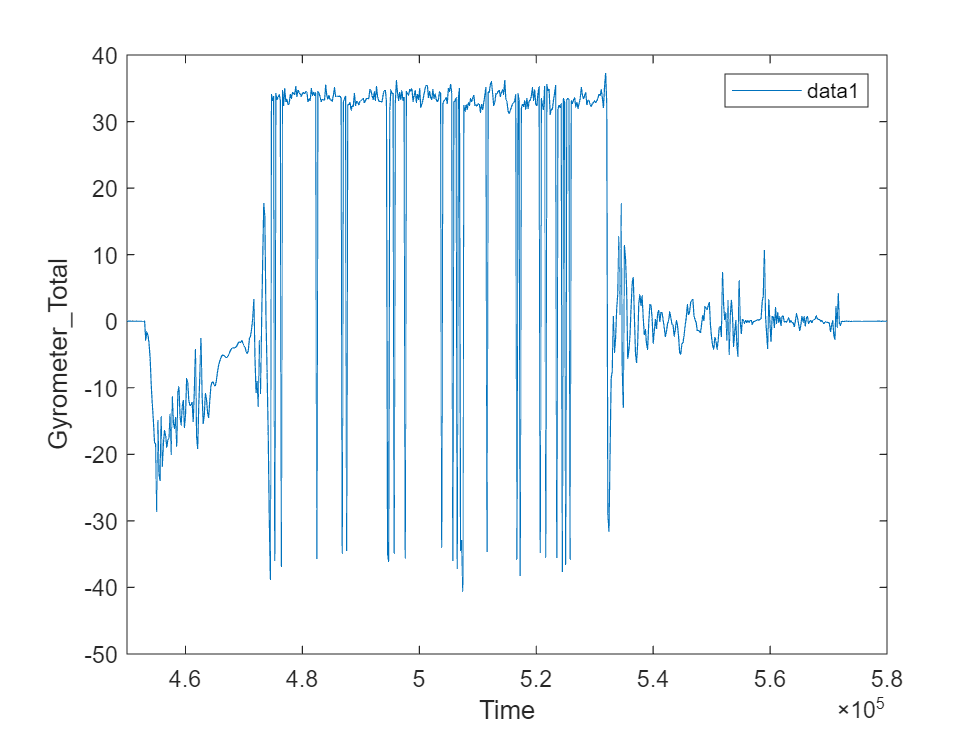

TemperaturePlot = plot(AtmoTable, "Time", "Gyrometer_Total");
xlim([450000,580000]);
legend

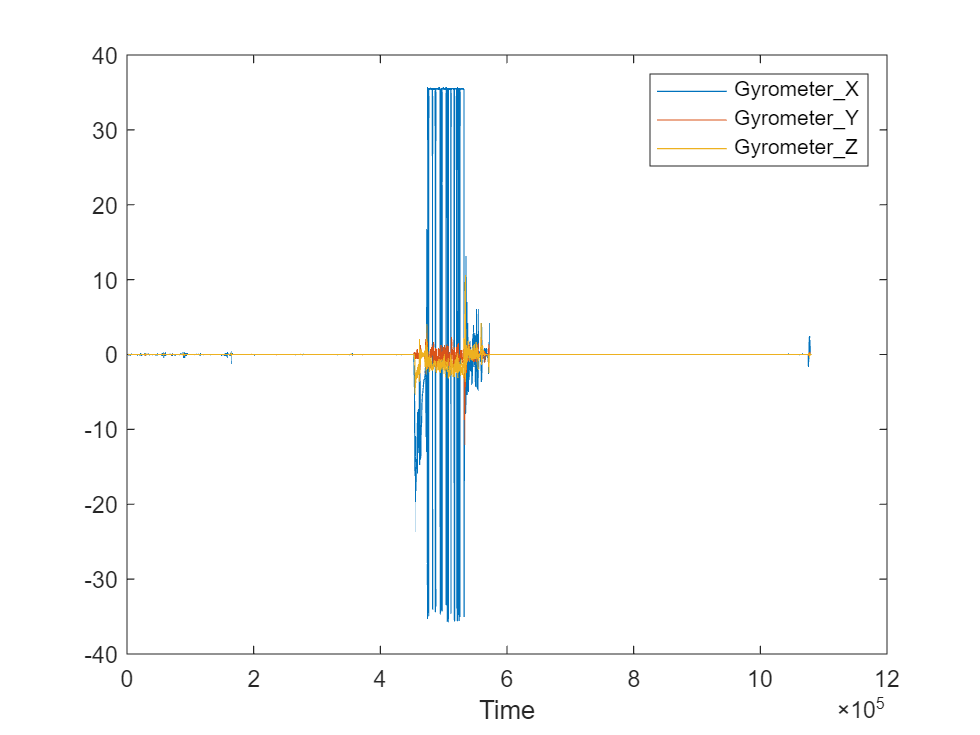

TemperaturePlot = plot(AtmoTable, "Time", ["Gyrometer_X", "Gyrometer_Y", "Gyrometer_Z"]);
legend

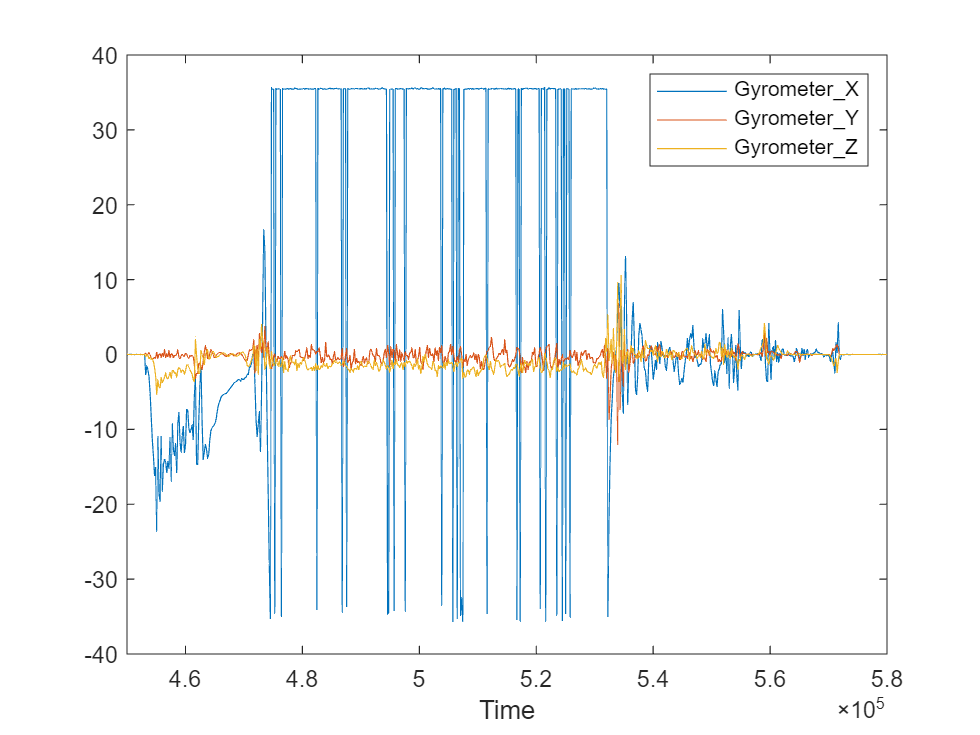

TemperaturePlot = plot(AtmoTable, "Time", ["Gyrometer_X", "Gyrometer_Y", "Gyrometer_Z"]);
xlim([450000,580000]);
legend

#### Linear Acceleration (m/s^2) vs Time

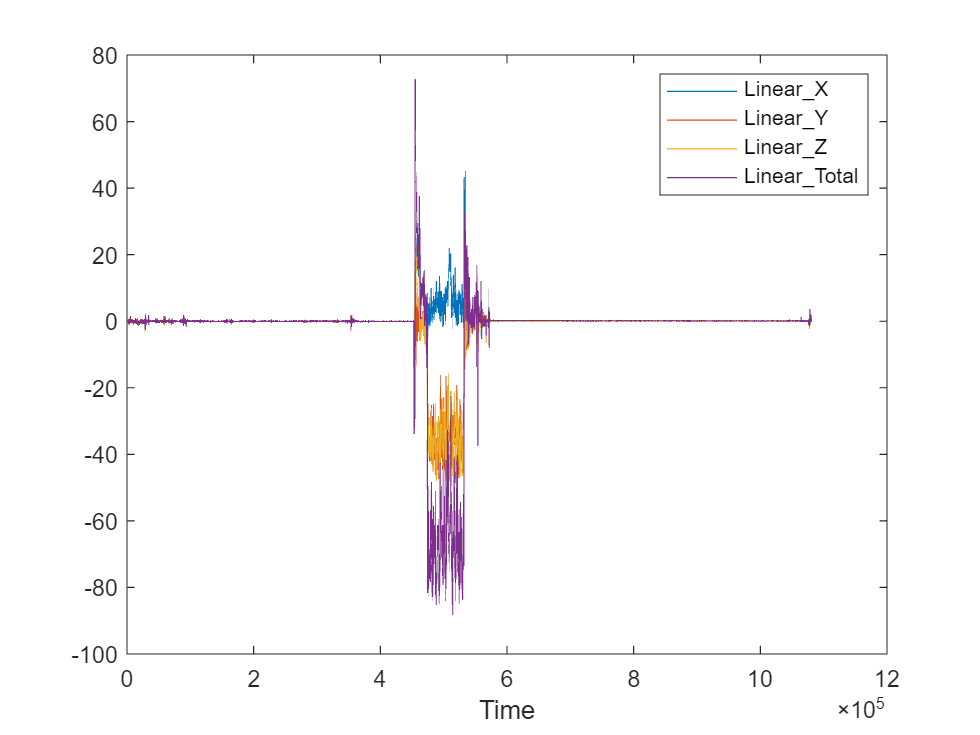

TemperaturePlot = plot(AtmoTable, "Time", ["Linear_X", "Linear_Y", "Linear_Z", "Linear_Total"]);
legend

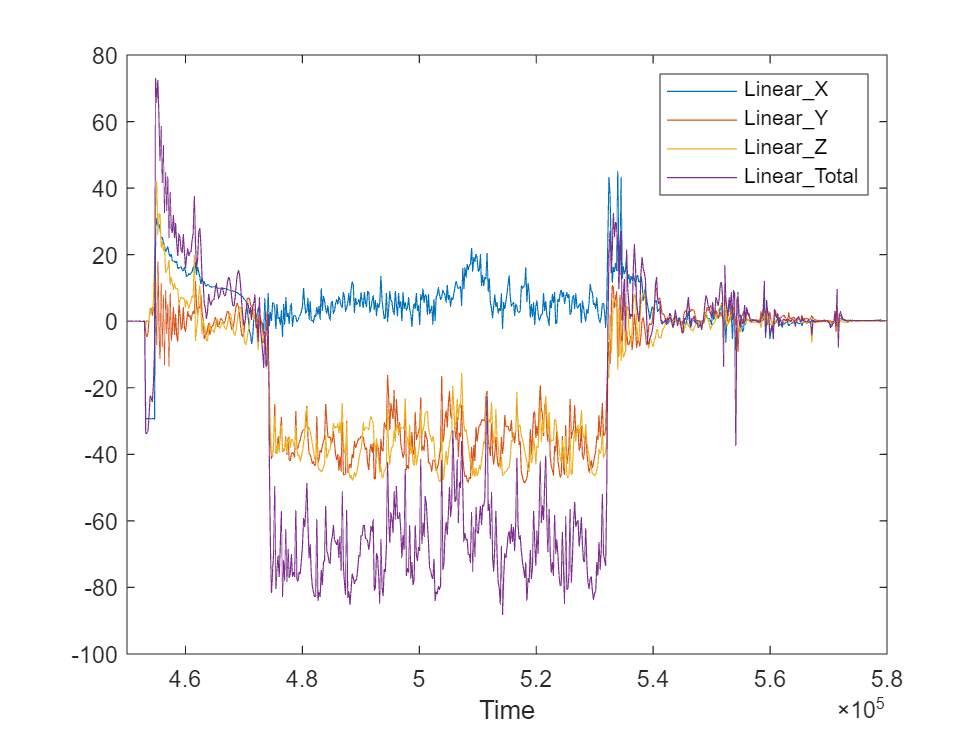

TemperaturePlot = plot(AtmoTable, "Time", ["Linear_X", "Linear_Y", "Linear_Z", "Linear_Total"]);
xlim([450000,580000]);
legend

#### Magnetism (uT) vs Time

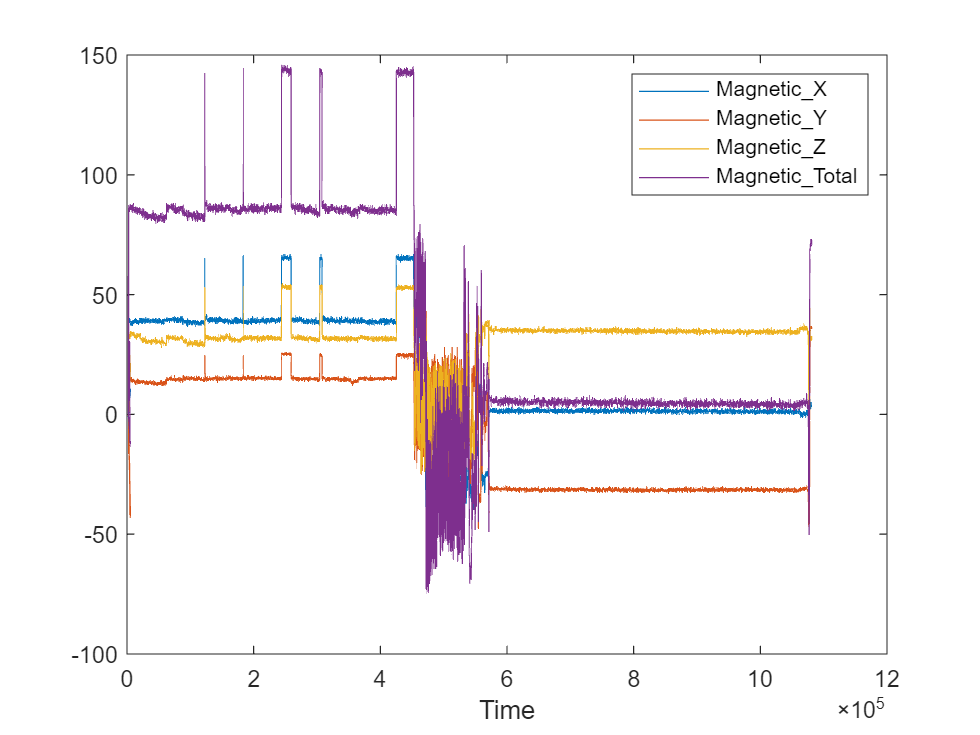

TemperaturePlot = plot(AtmoTable, "Time", ["Magnetic_X", "Magnetic_Y", "Magnetic_Z", "Magnetic_Total"]);
legend

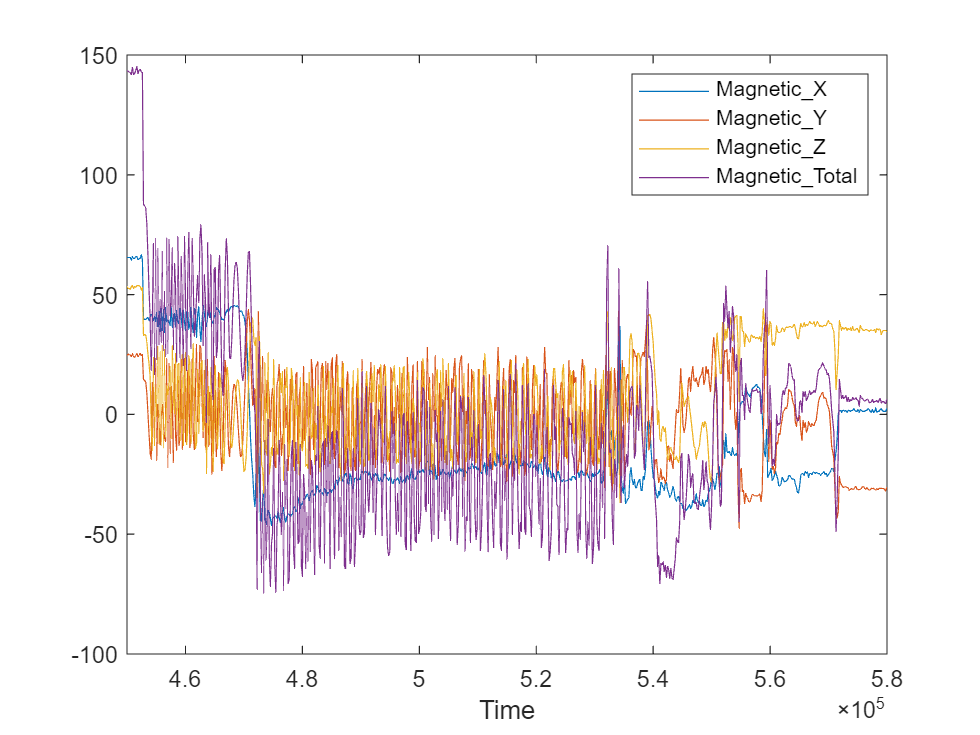

TemperaturePlot = plot(AtmoTable, "Time", ["Magnetic_X", "Magnetic_Y", "Magnetic_Z", "Magnetic_Total"]);
xlim([450000,580000]);
legend

#### Acceleration (m/s^2) vs Time

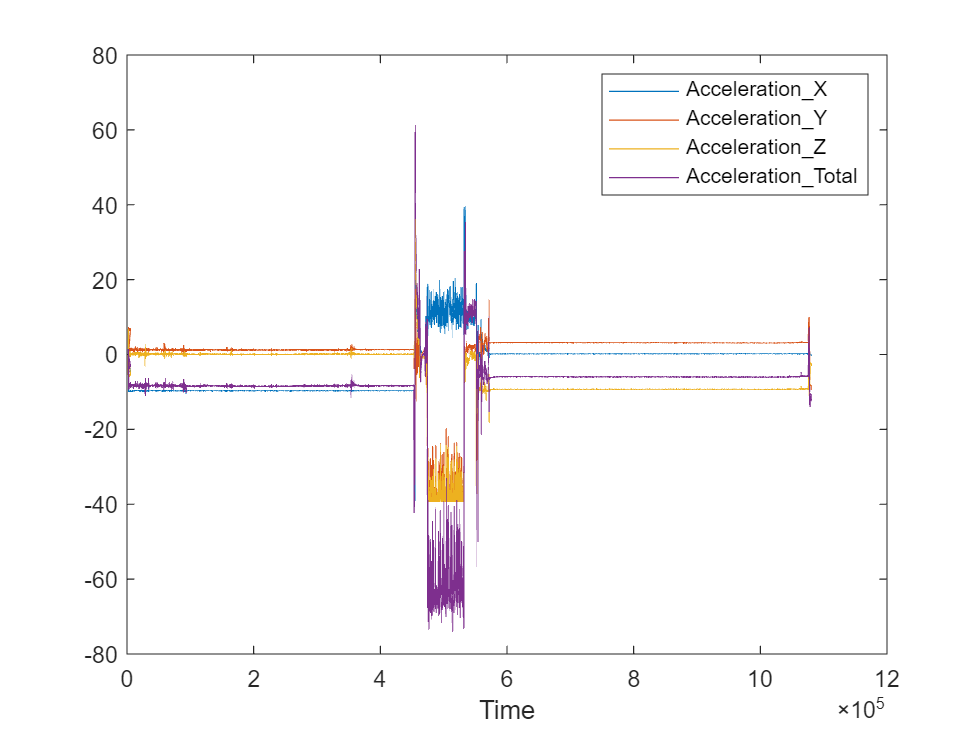

TemperaturePlot = plot(AtmoTable, "Time", ["Acceleration_X", "Acceleration_Y", "Acceleration_Z", "Acceleration_Total"]);
legend

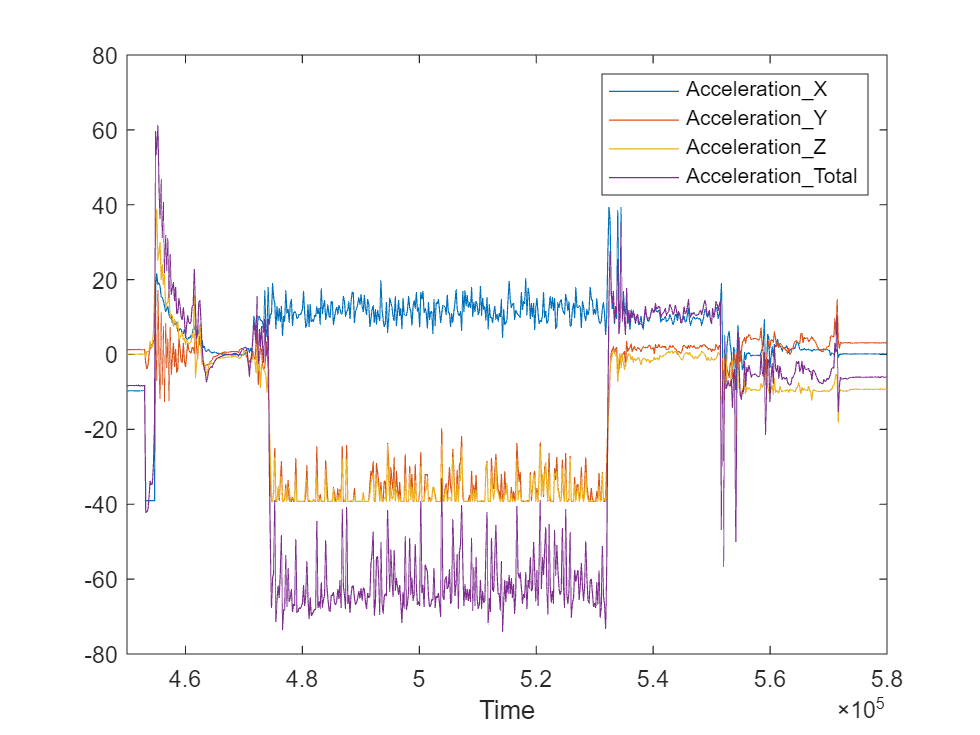

TemperaturePlot = plot(AtmoTable, "Time", ["Acceleration_X", "Acceleration_Y", "Acceleration_Z", "Acceleration_Total"]);
xlim([450000,580000]);
legend

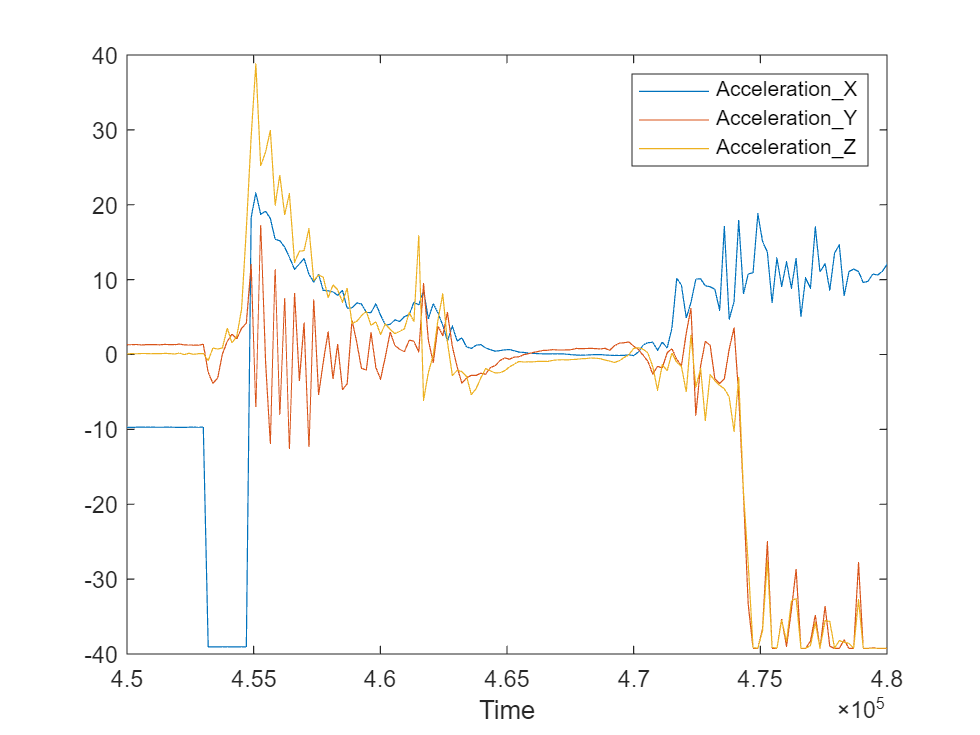

TemperaturePlot = plot(AtmoTable, "Time", ["Acceleration_X", "Acceleration_Y", "Acceleration_Z"]);
xlim([450000,480000]);
legend

Acceleration X

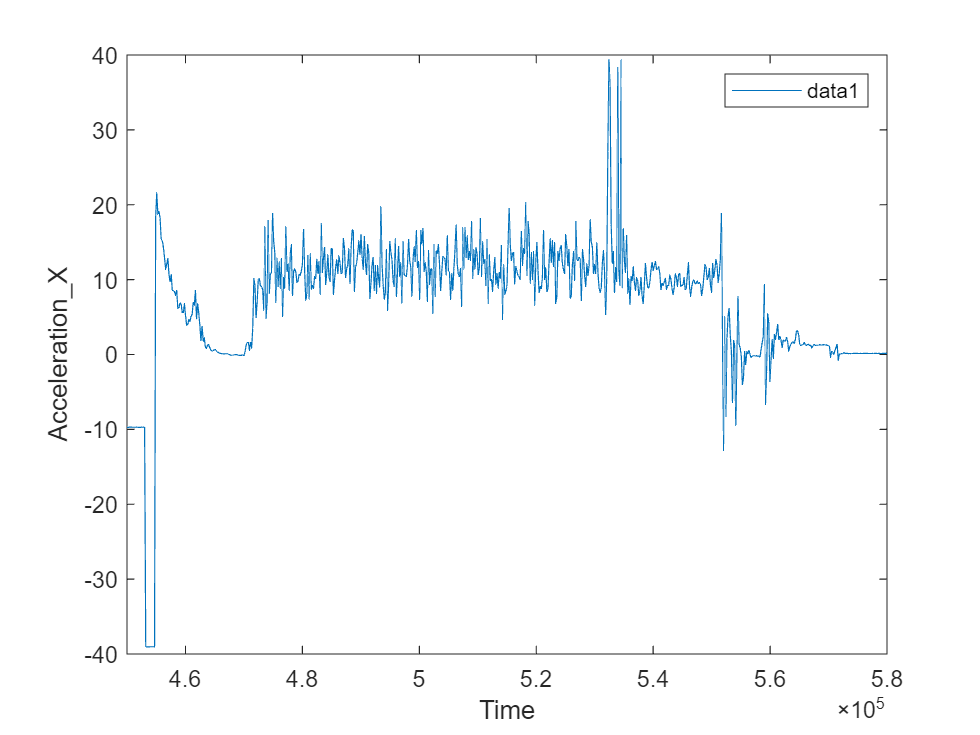

TemperaturePlot = plot(AtmoTable, "Time", "Acceleration_X");
xlim([450000,580000]);
legend

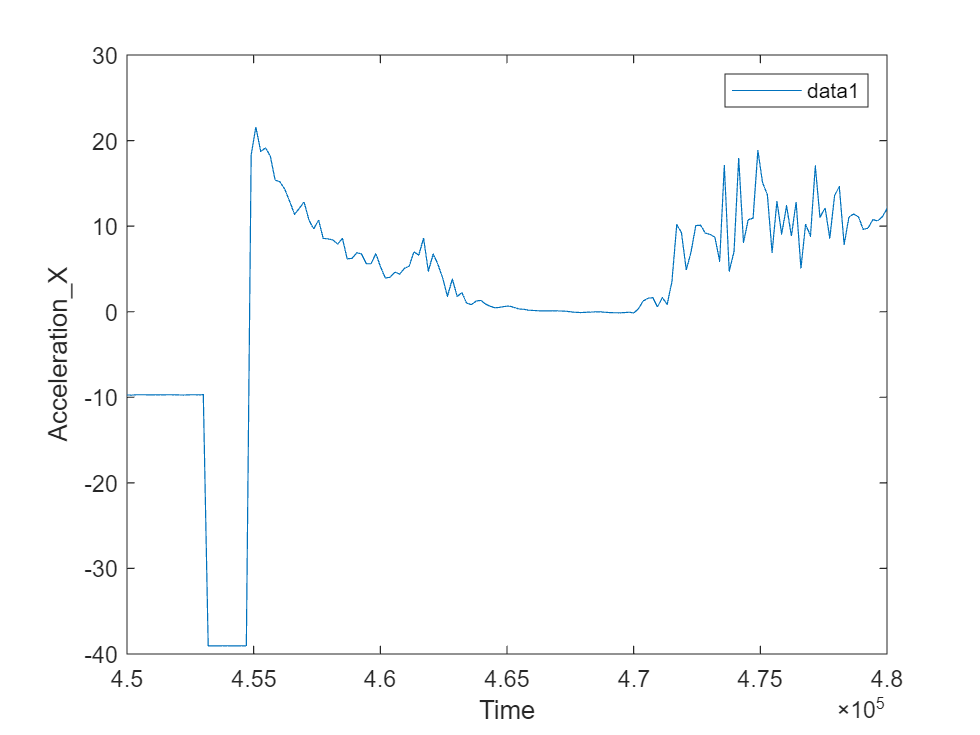

TemperaturePlot = plot(AtmoTable, "Time", "Acceleration_X");
xlim([450000,480000]);
legend

Acceleration Y

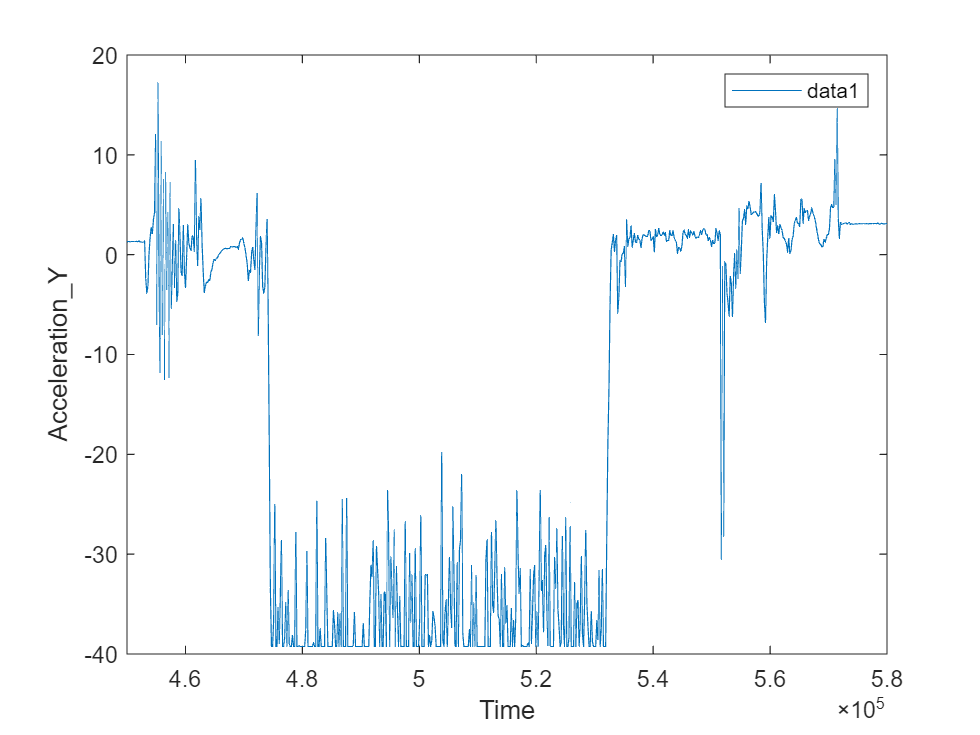

TemperaturePlot = plot(AtmoTable, "Time", "Acceleration_Y");
xlim([450000,580000]);
legend

Acceleration Z

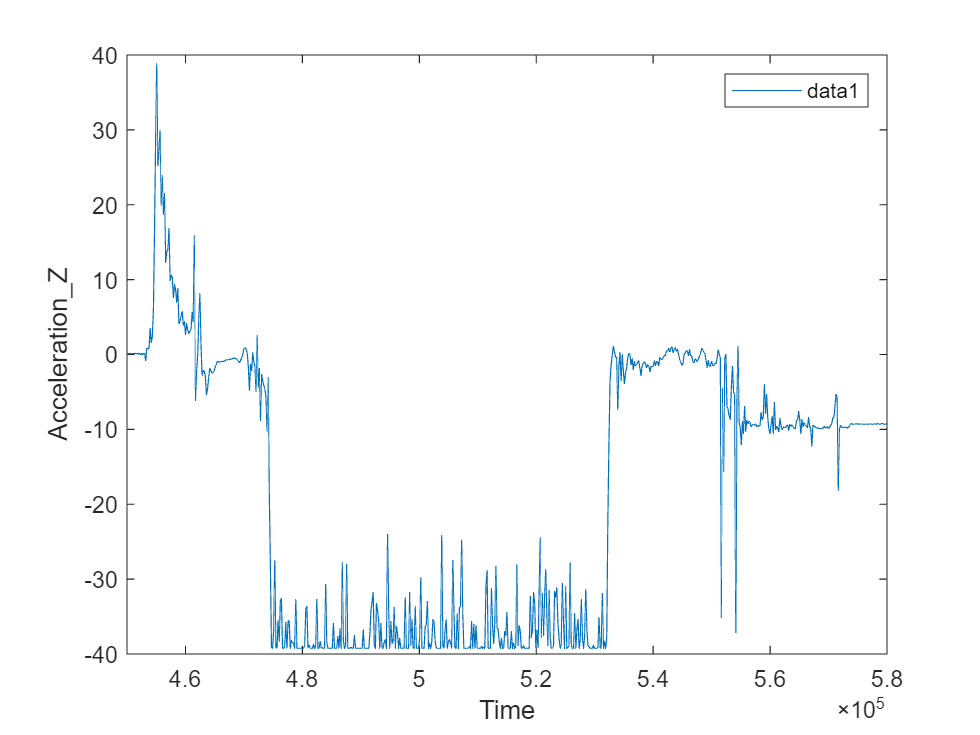

TemperaturePlot = plot(AtmoTable, "Time", "Acceleration_Z");
xlim([450000,580000]);
legend

#### Gravity (m/s^2) vs Time

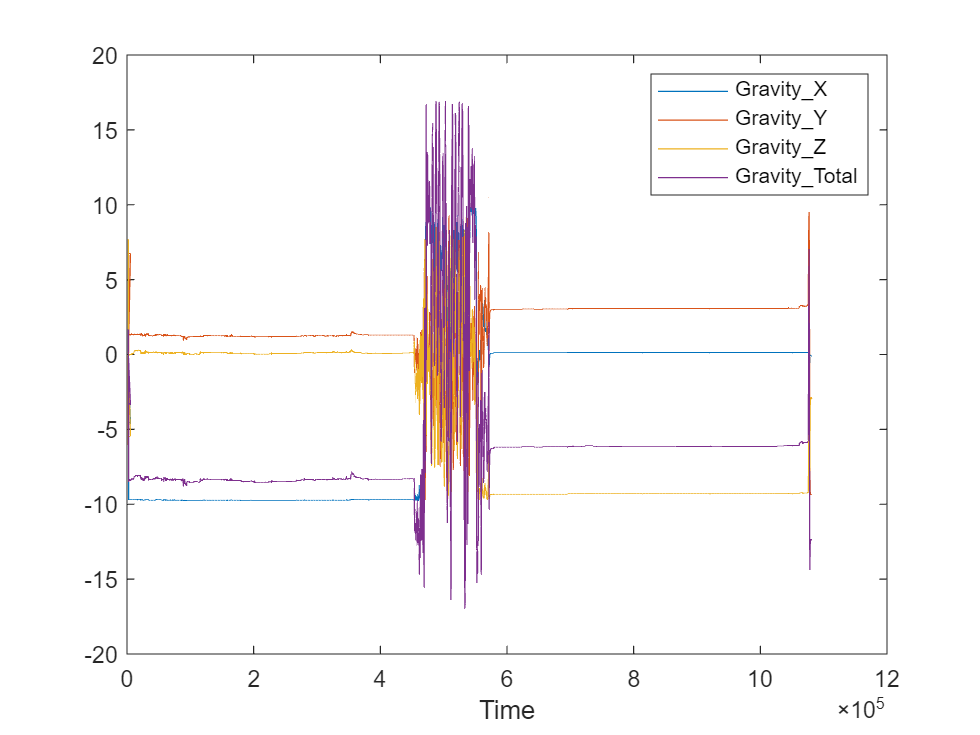

TemperaturePlot = plot(AtmoTable, "Time", ["Gravity_X", "Gravity_Y", "Gravity_Z", "Gravity_Total"]);
legend

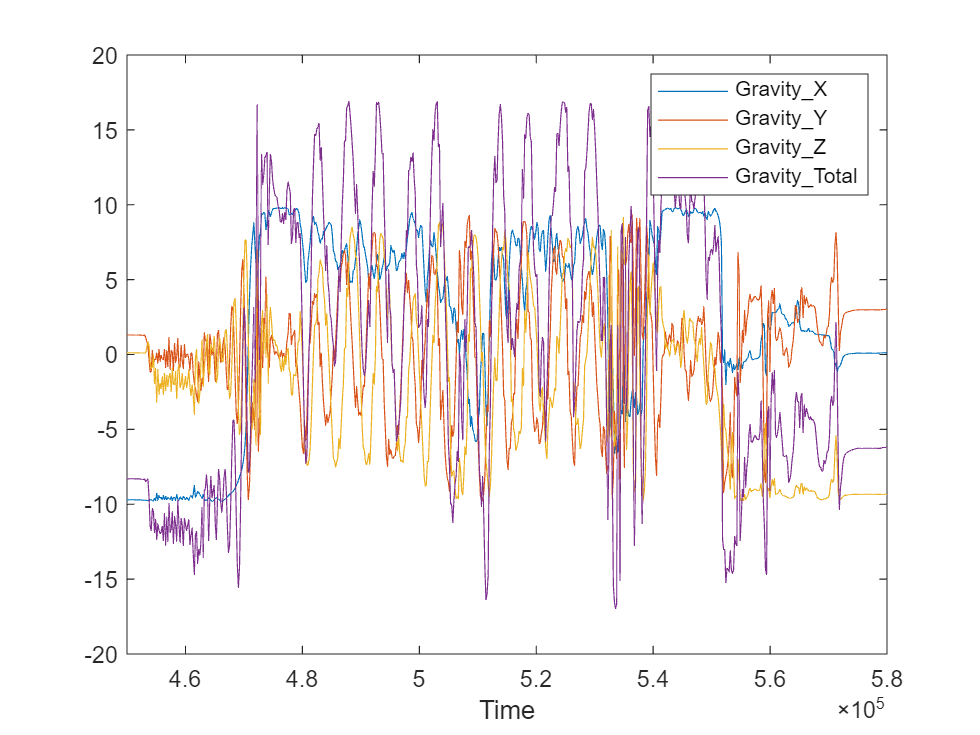

TemperaturePlot = plot(AtmoTable, "Time", ["Gravity_X", "Gravity_Y", "Gravity_Z", "Gravity_Total"]);
xlim([450000,580000]);
legend

#### Position (m * 10^-3) vs Time

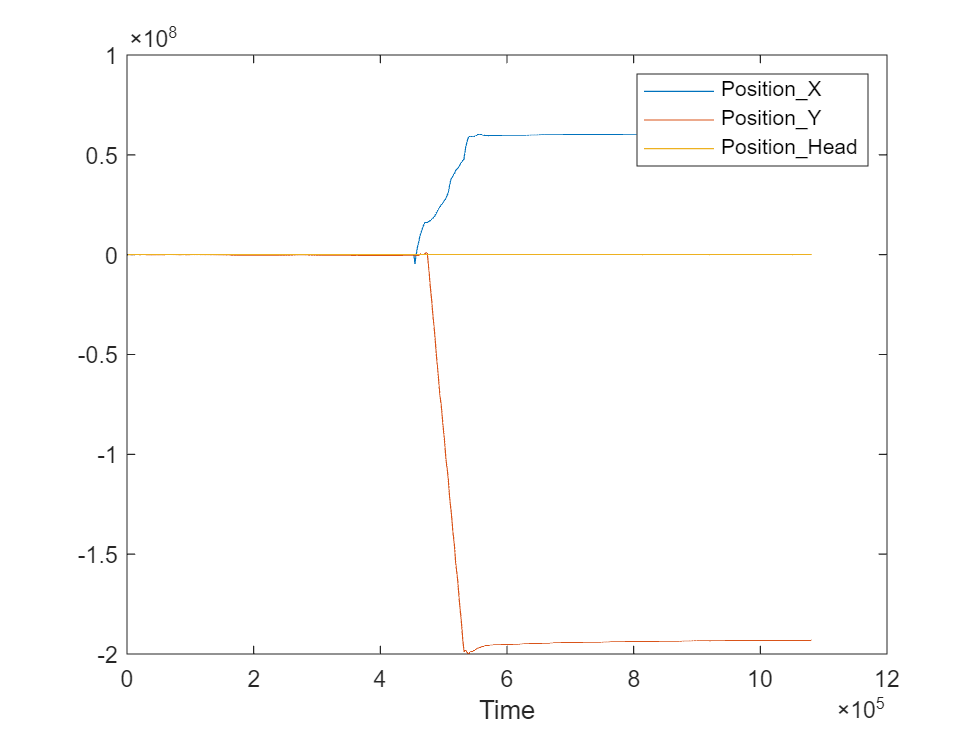

TemperaturePlot = plot(AtmoTable, "Time", ["Position_X", "Position_Y", "Position_Head"]);
legend

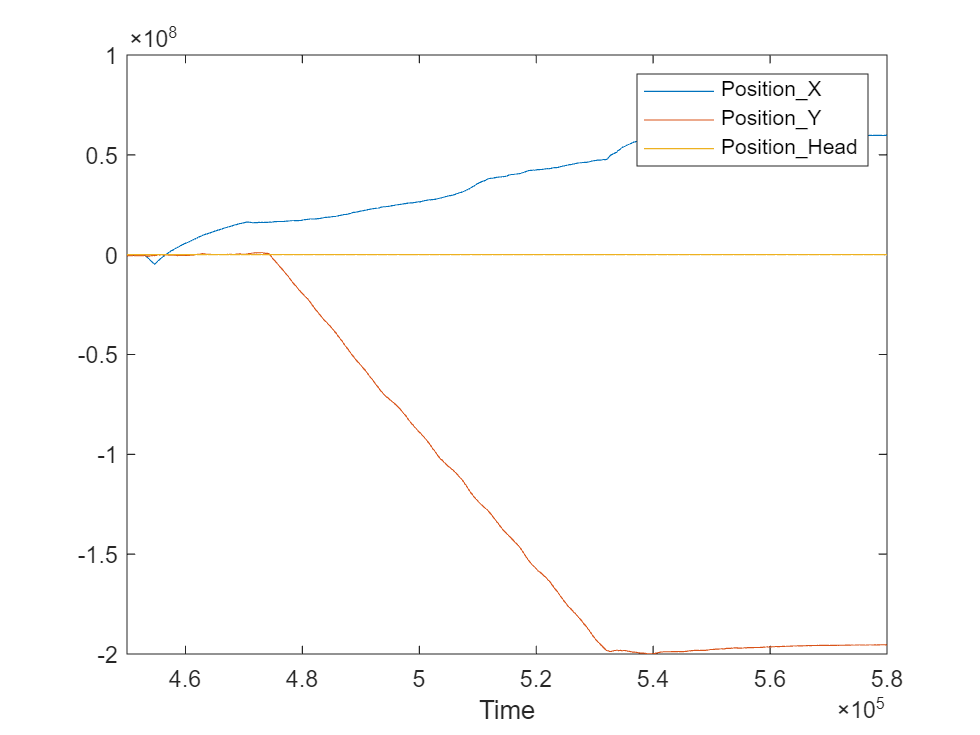

TemperaturePlot = plot(AtmoTable, "Time", ["Position_X", "Position_Y", "Position_Head"]);
xlim([450000,580000]);
legend

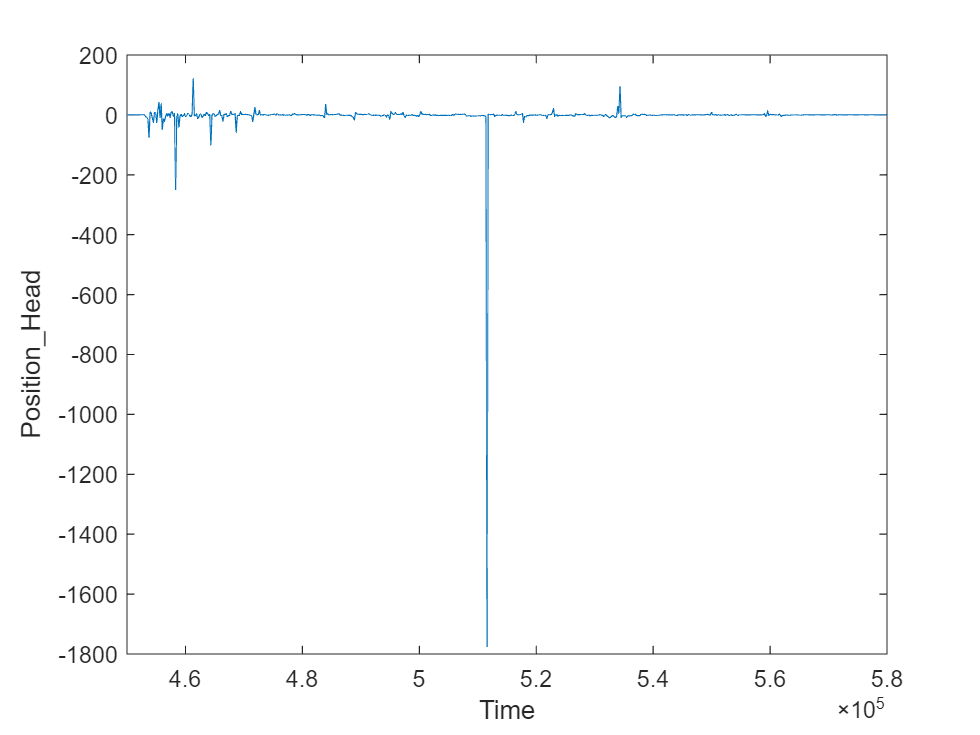

TemperaturePlot = plot(AtmoTable, "Time", "Position_Head");
xlim([450000,580000]);